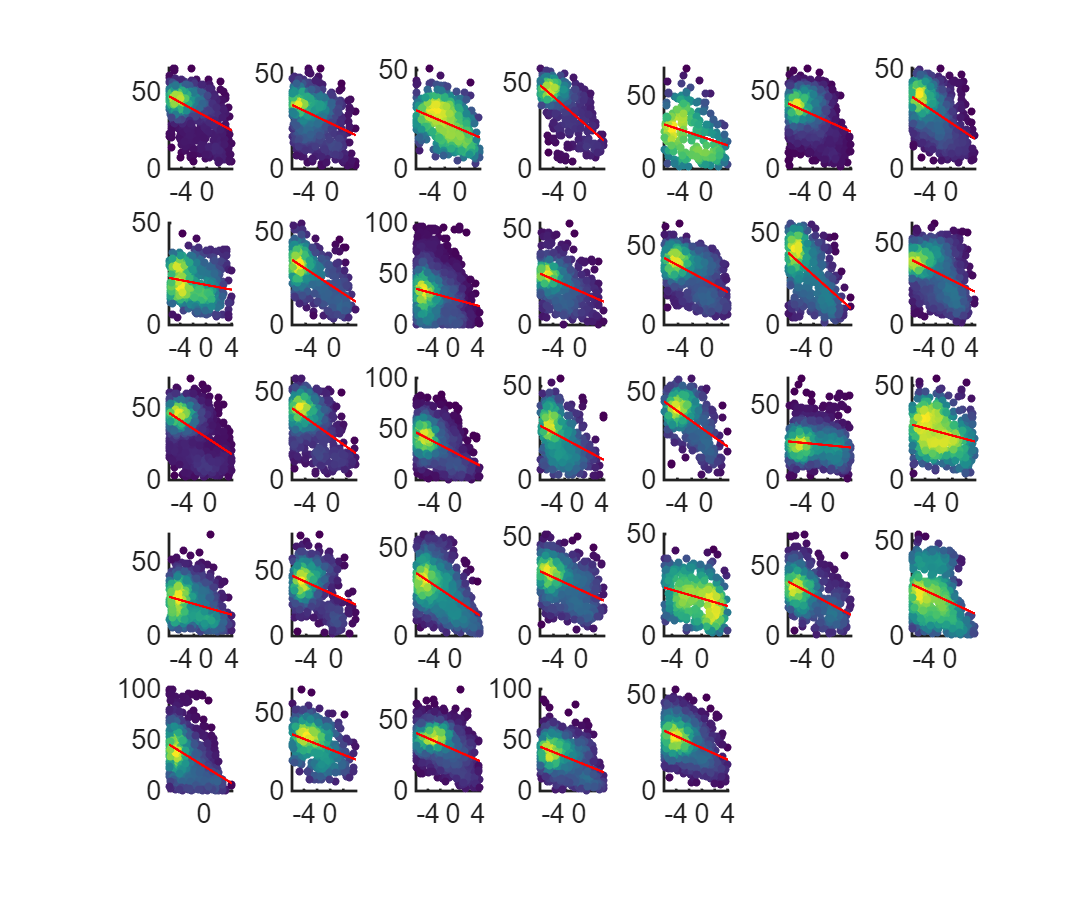

clc; clear;
load(fullfile('step4_IEDtw_TD-6d0_IT-100ms_fitting', ...
    'op6_IEDtw_fibN-VS-delay_fitting.mat'));
figure('Units', 'centimeters', 'Position', [5, 5, 36, 30]);
N = 0;
for nS = 1:length(subG)
    fibN = fibN_delay_corr(nS).fibN;
    IEDtwD = fibN_delay_corr(nS).delay;
    if isempty(fibN)
        continue;
    end
    [polyModel, Curve, Ftest] = fit_polyfit(fibN, IEDtwD, 1);
    N = N + 1; subplot(5, 7, N);
    f_densityScatter(fibN, IEDtwD, 2); hold on;
    plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
    set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 20, 'LineWidth', 2);
end